clc
clear all
close all

%loading data
load('Received.mat')

energy_val = 6.6034e-05

energy_val = 6.0693e-05

energy_val = 1.3198e-04

energy_val = 1.1249e-04

energy_val = 1.5531e-04

energy_val = 1.6073e-04

energy_val = 1.7425e-04

energy_val = 1.6745e-04

energy_val = 2.1975e-04

energy_val = 2.2606e-04

energy_val = 2.7208e-04

energy_val = 2.8253e-04

energy_val = 2.8950e-04

energy_val = 3.0573e-04

energy_val = 2.7355e-04

energy_val = 3.6193e-04

energy_val = 3.9448e-04

energy_val = 4.0292e-04

energy_val = 4.3191e-04

energy_val = 4.5051e-04

energy_val = 3.9295e-04

energy_val = 3.7173e-04

energy_val = 3.8975e-04

energy_val = 4.1702e-04

energy_val = 4.3341e-04

energy_val = 5.3209e-04

energy_val = 4.3078e-04

energy_val = 5.9502e-04

energy_val = 5.0786e-04

energy_val = 6.4634e-04

energy_val = 7.0079e-04

energy_val = 8.0737e-04

energy_val = 9.5304e-04

energy_val = 0.0011

energy_val = 0.0011

energy_val = 0.0017

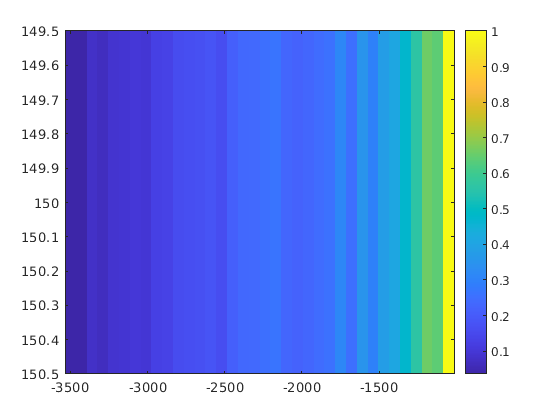

all_x_coor = -3500:70:-1000;
all_y_coor = 15:50:350;
all_y_coor = 150;
energy_values = zeros(size(all_y_coor,2), size(all_x_coor,2));
i=0;
for x = all_x_coor
    i=i+1;
    j=0;
%     x
    for y=all_y_coor
        j=j+1;
        sig = get_signal_at_a_point(RecSig,x, y);
        %energy_sig = sig.^2;
        %energy_val = sum(sum(energy_sig));
        energy_val = max(max(sig))
        energy_values(j,i) = energy_val;
        image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
        colorbar
        
    end
    pause(0.5)
end

dummy_en = []


dummy_en =

     []



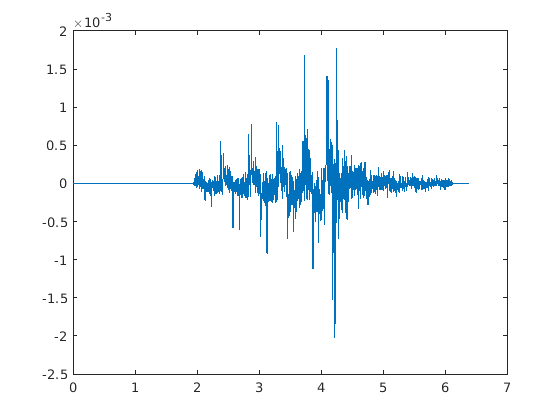

for i = [-500:70:-100]
sig = get_signal_at_a_point(RecSig,i, 150);
plot(t,sig)
pause(0.5)
dummy_en(end+1)=max(max(sig));
end

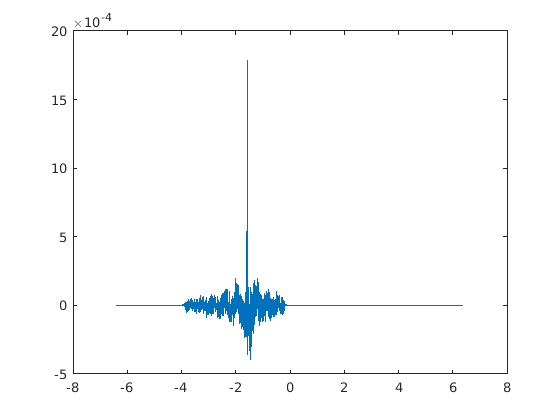

sig = get_signal_at_a_point(RecSig,-1000, 150);
plot(t,sig)

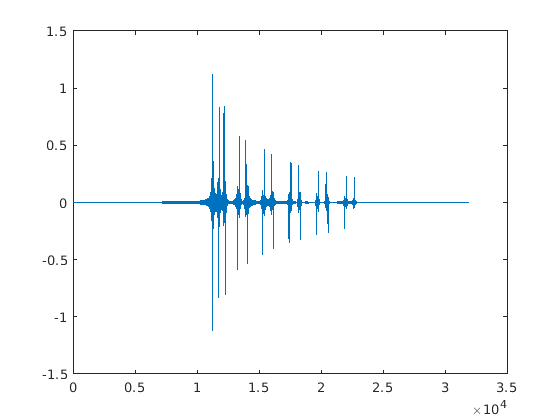

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

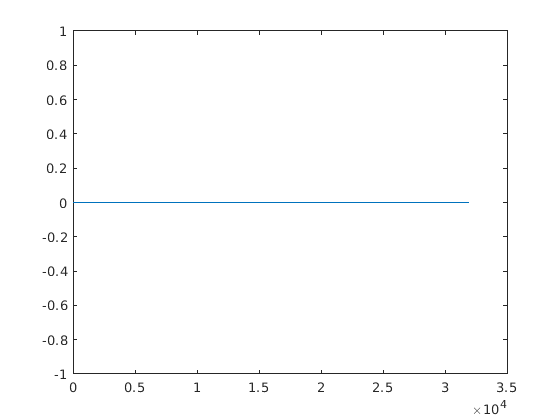


% plot(green(0, 1*25, 1500, 150, flip(RecSig(1,:)),t))

function all_sig = get_signal_at_a_point(RecSig, destination_x, destination_y)
dt = 2e-4;
% t = -6.4+dt:dt:6.4;
t = dt:dt:6.4;
all_sig = 0;
for i = 1:9
    recv_signal = RecSig(i,:)';
%     disp('rcv signal')
%     plot(recv_signal)
    padding = zeros(size(t,2)-size(recv_signal,1),1);
    padded_recv_signal = cat(1,padding,recv_signal);
    
%     disp('padded rcv signal')
%     figure()
%     plot(padded_recv_signal)
%     
    reversed_padded_recv_signal = flip(padded_recv_signal);
%     disp('reveresed padded rcv signal')
%     figure()    
%     plot(t,reversed_padded_recv_signal)
    
    sig = green(0, i*25, destination_x, destination_y, reversed_padded_recv_signal,t);
    if all_sig==0
        all_sig = sig;
    else
        all_sig = all_sig+sig;
        %plot(all_sig)
        %pause(0.5)
    end
%     disp('reconstructed_signal')
%     figure()
%     plot(sig)
    
%     
end
%%%%%%

end


function R = green(xs, zs, x, z,signal, t)
h = 350; %max_height
xs = xs;
zs = zs;
x = x;
z = z;
c = 1500;

dt = 2e-4;
fs = 1/dt;

%fs = 1.0e4;

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end



